## Problem 7.5 

Load the file time _ freq4.mat 

    - signal `x`: 2 sinusoids closely spaced in frequency and in time (0.1 s and 5 Hz, fs = 500Hz).

Apply the CWT using the Morlet wavelet with an `a` (range: [1 and 1/200]).

Repeat for Mexican Hat wavelet. Plot only the contour plots. 

*Taking the log of the scale variable, *`a`*, before plotting will improve the visibility of the two*

*frequencies. Note that they both give excellent time resolution with a noticeable gap*

*between the two frequencies. Also note that one of the wavelets shows slightly greater*

*differences between the two closely spaced frequencies.*

load('time_freq4.mat', 'x')

fs = 500;                       % Sampling frequency
Ts = 1/fs;                      % Calculate Ts
N = length(x);                  % Get data length
t = (1:N)/fs;                   % Time vector for plotting
f = (1:N)*fs/N;                 % Frequency vector for plotting

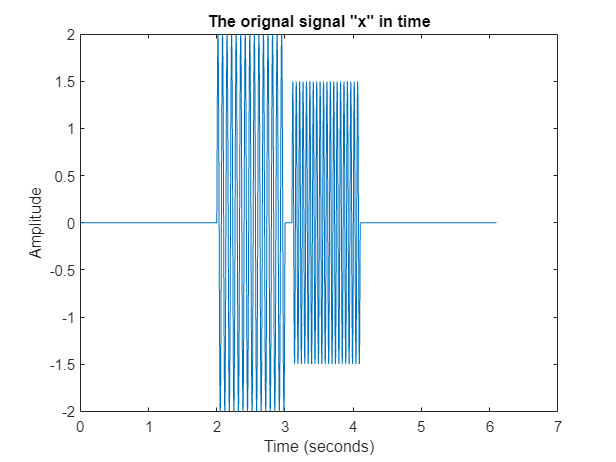


% Not part of assignment, just looking at the signal
plot(t,x)
xlabel('Time (seconds)');
ylabel('Amplitude');
title('The orignal signal "x" in time');


% Not part of assignment, just looking at the Fourier transform of signal
ft = (fft(x));
plot(f(1:end/5),abs((ft(1:end/5))));

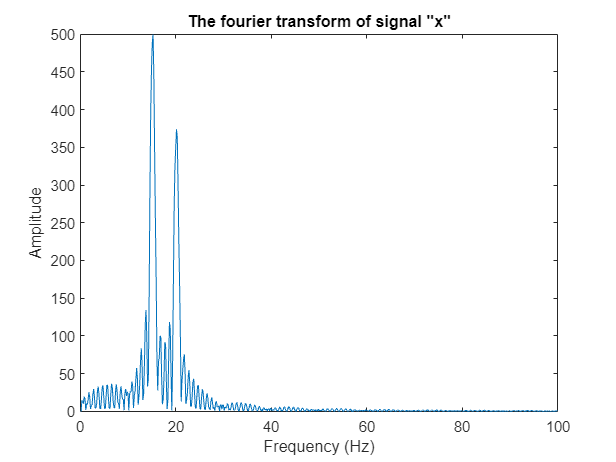

xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('The fourier transform of signal "x"');

Notes: raw signal has 15 peaks/sec and 20 peaks/sec for the 2 sinuosids, respectively, with a delay of 0.1 s (showing the spacing mentioned in the problem statement)

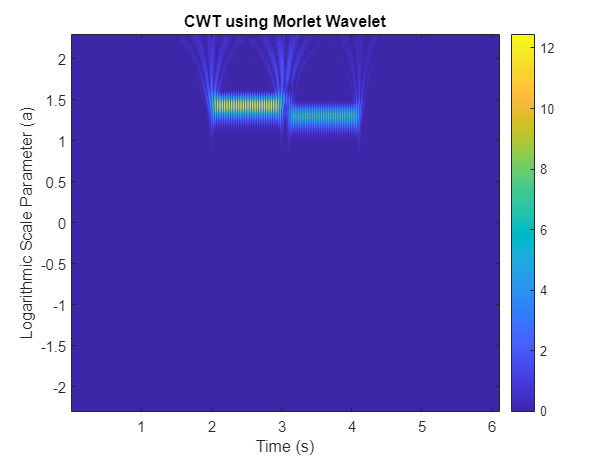

%% CWT

% Define the range of scale parameter a
a = logspace(log10(200), log10(1/200), 100); % range of a from 1 to 1/200 in log scale
a_lin = linspace(1, 1/200, 100); % and in linear scale

% Perform CWT using Morlet wavelet
morlet_cwt = cwt(x,a,'morl');

% Plot the contour plot of CWT using Morlet wavelet
figure;
contourf(t,log10(a),abs(morlet_cwt),40,'LineStyle','none');
colorbar;
title('CWT using Morlet Wavelet');
xlabel('Time (s)');
ylabel('Logarithmic Scale Parameter (a)');

% Perform CWT using Mexican Hat wavelet
mexican_cwt = cwt(x,a,'mexh');
mexican_cwt_lin = cwt(x,a_lin,'mexh');

% Plot the contour plots of CWT using Mexican Hat wavelet
figure('Name', 'Post Filtering w/ Mexican Hat');
subplot(1,2,1);
contourf(t,log10(a),abs(mexican_cwt),40,'LineStyle','none');
colorbar;
xlabel('Time (s)');
ylabel('Logarithmic Scale Parameter (a)');

Taking the log of the scale variable*, *`a`*,* compresses the scale axis, allowing the details in the high-frequency range to be more easily discerned.

In some cases, the frequency content of the signal may be concentrated in a particular range of scales, and taking the logarithm can help to reveal these features more clearly.

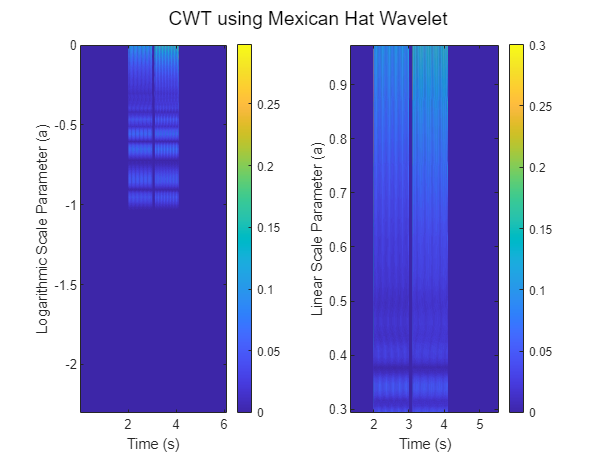

subplot(1,2,2);
contourf(t,a_lin,abs(mexican_cwt_lin),40,'LineStyle','none');
colorbar;
xlabel('Time (s)');
ylabel('Linear Scale Parameter (a)');

sgtitle('CWT using Mexican Hat Wavelet');